# Exercise 2 SOLUTIONS

## Introduction

The objectives of this exercise are:

- Formulate an ***S***-matrix in MATLAB

- Rearrange an ***S***-matrix and note the effect

- Calculate the degrees of freedom and discuss its meaning

- Perform metabolic flux analysis (using a function, but you should know the equation)

- Critically interpret the results from MFA calculations 

**Report:** To help each other, you are encouraged to work in pairs on this exercise. This exercise is not graded and no report needs to be handed in. Meanwhile, the topics being discussed are exam material. **You are advised to work on this exercise *****after***** you have worked through the pre-study material for "Construct the S-matrix and flux analysis", and *****before***** the lecture on Exercise 2**, where help will be provided and the solutions to the exercise will be discussed. The solution to this exercise will also be made available on Canvas.

**Book contents:** This exercise covers chapters 2, 9 and 12 from the Systems Biology textbook: [https://doi.org/10.1017/CBO9781139854610](https://doi.org/10.1017/CBO9781139854610).

**Exercise files:** The current Live Script is accompanied by a `solveMFA.m` function file that is required for some of the questions. You can modify this script when answering the questions, also feel free to take down notes within this document. Via `Export -> Export to PDF...` in the menu bar you can then generate a file that you can also study outside of MATLAB.

% Check whether solveMFA is in the current working directory
pwd                  % This is the current working directory

ans = 'C:\Users\eduardk\OneDrive - Chalmers\Documents\Work\Teaching\KMG060\2021\Exercise2_Smatrix\exercise2_code'

isfile('solveMFA.m') % If ans = 0, then change working directory to location of solveMFA.m

ans = logical
   1


**Background: **In this exercise we will construct an ***S***-matrix, perform metabolic flux analysis and have a look at rate equations. As an example, we will look at PHB production in yeast. In this paper the authors are looking to improve PHB production through diverting the flux and the effect of different carbon sources.

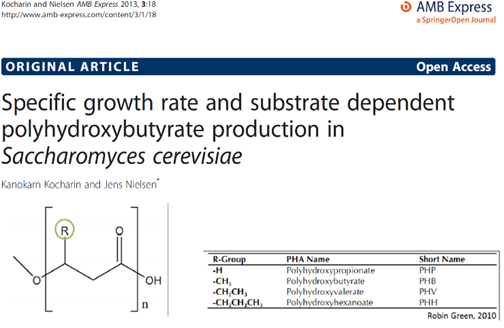

## Stoichiometric matrix

A simplified metabolic network is shown below, including glycolysis, PPP, TCA cycle and PHB production. Note that some reactions are lumped and simplified: AASyn represents amino-acid synthesis; NuclSyn represents nucleotide synthesis; ATPsyn represents ATP synthase. PPP, representing the transaldolase and transketolase reactions, has the reaction equation 2 Ribu5P + R5P → 2 Fru6P + GA3P.

Growth represents the polymerization of biomass precursors to form new biomass. ATPM is an ATP hydrolysis reaction that represents non-growth associated energy costs. Both of these will be discussed in more detail later in the course.

Because we apply the steady-state assumption, we can further simplify this network by lumping linear reactions and removing linear-dependent co-factors. Indicate which simplifications can be made on the network below, and then compare this to the reduced network that is shown further down this Live Script. Did you find all simplifications?

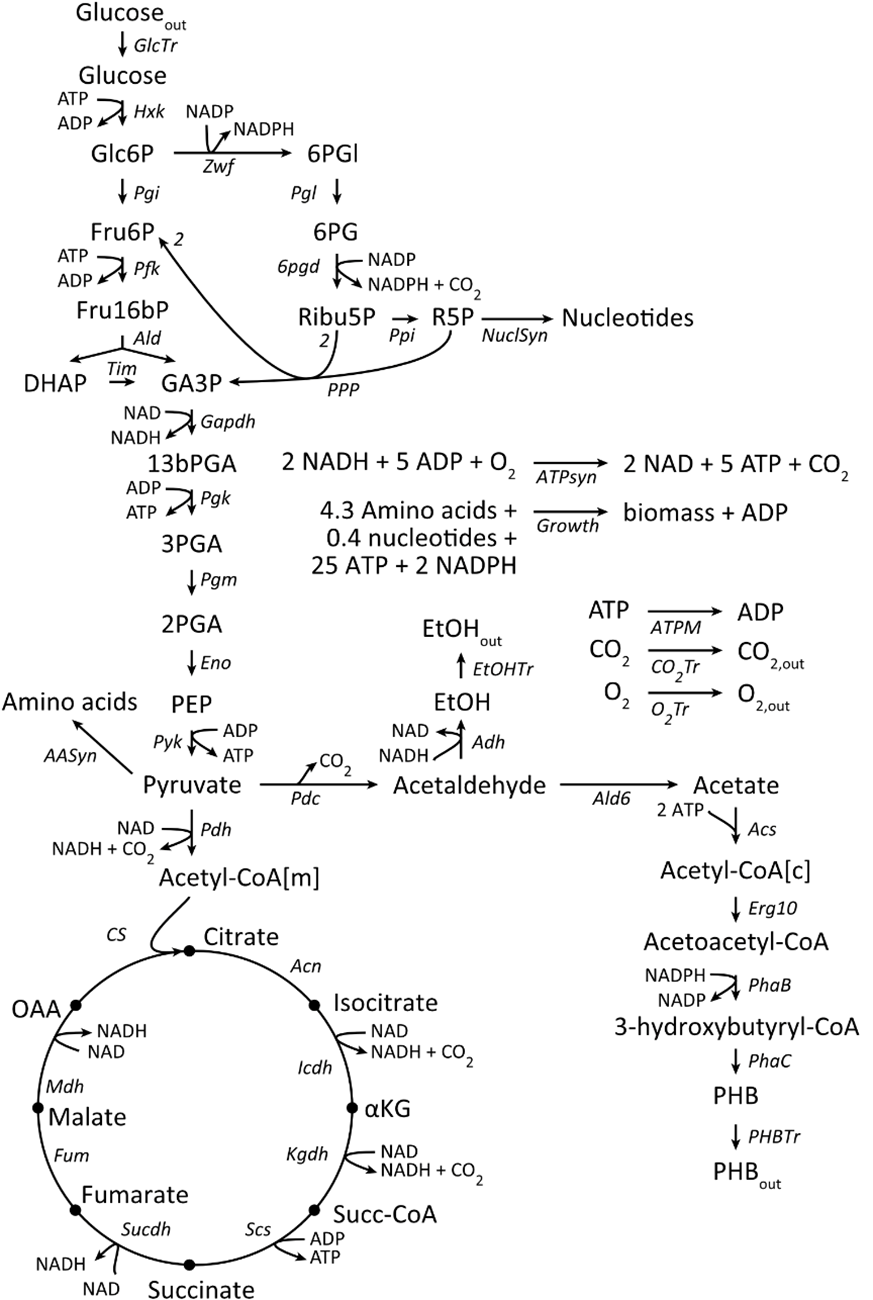

#### Q1: write down how to above network can be simplified:

**Answer**: Overview of simplified network:

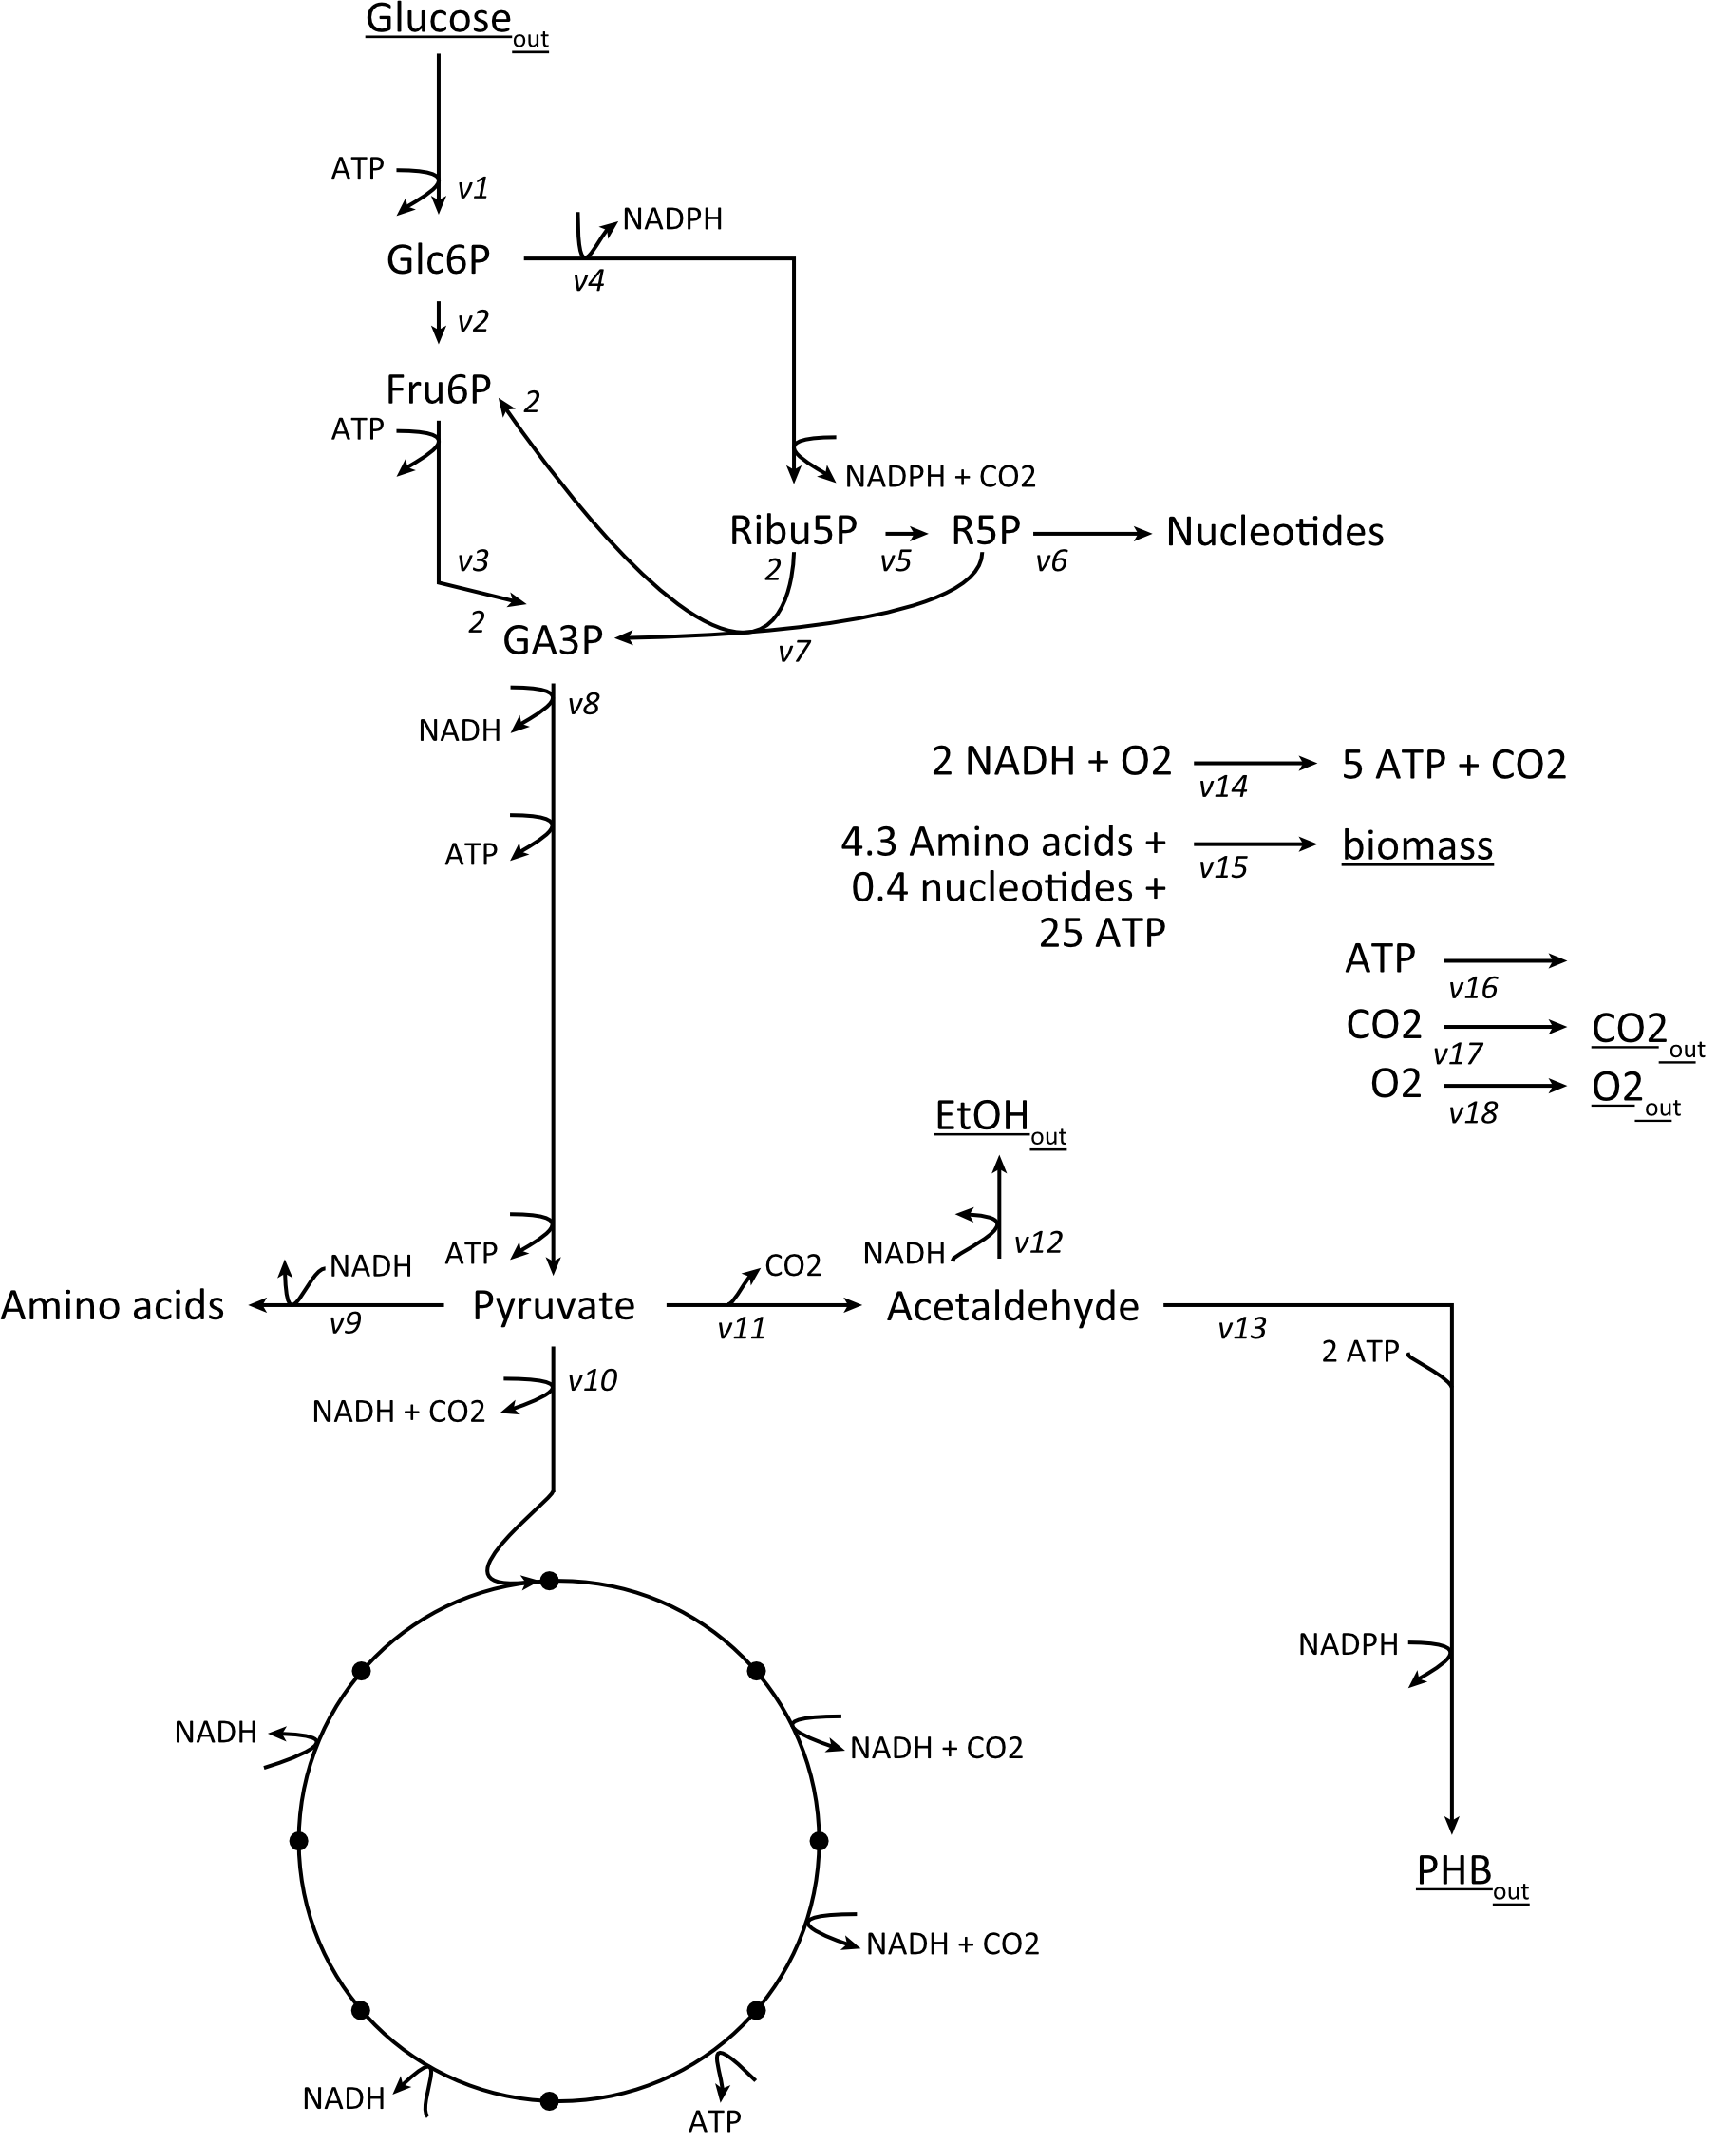

First try to find out the many ways this network can be simplified before looking at the reduced network!

**Reduced network:**

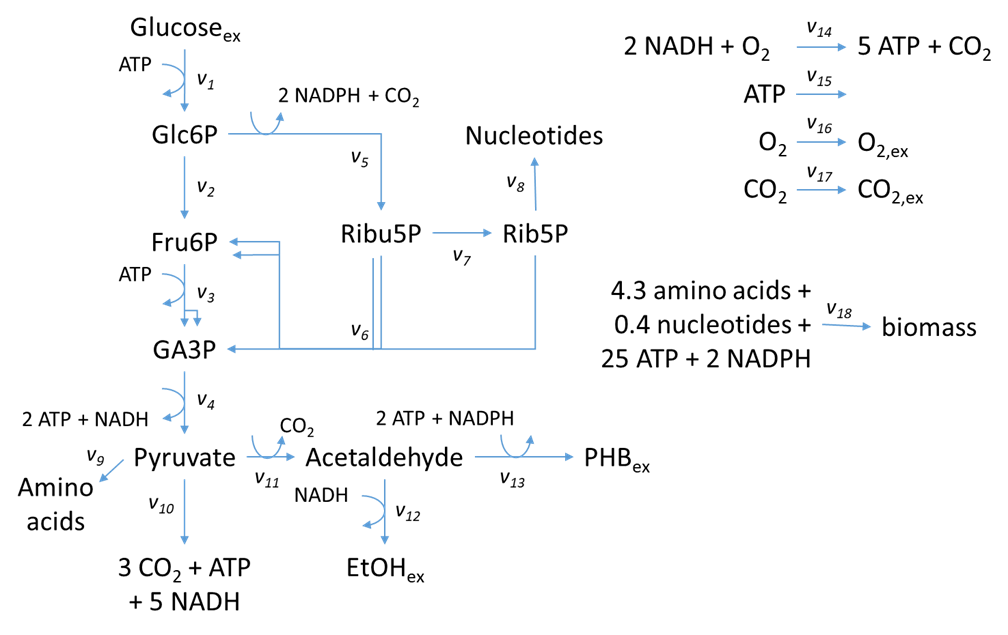

Below the **S**-matrix of the reduce network is shown, but one column and one row are not filled in yet (indicated with `X`).

**Q2**: Which reaction and metabolite are not yet filled in? You can assume that order of reactions is the same as in the figure: first *v1*, followed by *v2*, *v3* and so forth, with *v18* last. **Answer**: Third column: *v**3*; eigth row: ATP. Order of metabolites can be inferred from knowing the order of the reactions: Glc6P; Fru6P; GA3P; Pyruvate; Ribu5P; Rib5P; Acetaldehyde; ATP; NADH; NADPH; O2; CO2; Amino acids; Nucleotides; Glucoseex; O2,ex; CO2,ex; EtOHex; PHBex; biomass.

**Q3**: Replace every `X` with the appropriate stoichiometric coefficient. Afterwards, run the section to generate the **S**-matrix in MATLAB.

S=[1,  -1,   0,   0,  -1,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0
   0,   1,  -1,   0,   0,   2,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0;
   0,   0,   2,  -1,   0,   1,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0;
   0,   0,   0,   1,   0,   0,   0,   0,  -1,  -1,  -1,   0,   0,   0,   0,   0,   0,   0;
   0,   0,   0,   0,   1,  -2,  -1,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0;
   0,   0,   0,   0,   0,  -1,   1,  -1,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0;
   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   1,  -1,  -1,   0,   0,   0,   0,   0;
  -1,   0,  -1,   2,   0,   0,   0,   0,   0,   1,   0,   0,  -2,   5,  -1,   0,   0,  -25;
   0,   0,   0,   1,   0,   0,   0,   0,   0,   5,   0,  -1,   0,  -2,   0,   0,   0,   0;
   0,   0,   0,   0,   2,   0,   0,   0,   0,   0,   0,   0,  -1,   0,   0,   0,   0,  -2;
   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,  -1,   0,  -1,   0,   0;
   0,   0,   0,   0,   1,   0,   0,   0,   0,   3,   1,   0,   0,   1,   0,   0,  -1,   0;
   0,   0,   0,   0,   0,   0,   0,   0,   1,   0,   0,   0,   0,   0,   0,   0,   0,  -4.3;
   0,   0,   0,   0,   0,   0,   0,   1,   0,   0,   0,   0,   0,   0,   0,   0,   0,  -0.4;
  -1,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0;
   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   1,   0,   0;
   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   1,   0;
   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   1,   0,   0,   0,   0,   0,   0;
   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   1,   0,   0,   0,   0,   0;
   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   0,   1];

**Q4**: Is the **S**-matrix the **S_tot**, **S_in** or **S_ex** matrix? **Answer**: **S_tot** as the boundary metabolites glucose_ex etc. are also included.

**Q5**: How many degrees of freedom does the reduced network have, when does this make the model determined and how does this effect the calculation of fluxes? **Answer**: There are 18 reaction and 14 internal metabolites. Degrees of freedom is then 18−14 = 4. If the rates of 4 linearily independent reactions are known, the model is determined, which means that all other fluxes can precisely and uniquely be calculated. Less than 4 known reaction rates makes the system underdetermined: non-unique solutions....

**Q6**: From the reduced network, give two sets of reactions that would match the degrees of freedom and either  … 

- … not be sufficient to calculate all other fluxes. **Answer**: for instance *v1*, *v2*, *v3* and *v4.*

- … be sufficient to calculate all other fluxes (this might be hard to see on paper, but we'll check this in MATLAB later). **Answer**: *v1*, *v12*, *v16* and *v18.*

## Metabolic Flux Analysis

**Q7**: Assume that we know the ethanol secretion (v12), O2 consumption (v16), CO2 excretion (v17) and growth rate (v18), with values 0, -5, 11 and 0.05, respectively. Perform metabolic flux analysis to find out the rate of PHB production in these conditions. **Answer**: v13 = 1.0575.

%% Perform MFA step by step
% Define S_in and S_ex
S_in  = S(1:14, :);  % Rows are specified first, then columns. Take row 1 to 14 (1:14) and all columns (:).
S_ex = S(15:end, :); % Take rows 15 until the last (15:end) and all columns (:).

% Define which fluxes are measured and which will be calculated
measFluxes = [12, 16, 17, 18];
calFluxes = [1:11, 13:15];

% Generate the S_in,meas and S_in,cal matrices
S_inmeas = S_in(:,measFluxes);
S_incal = S_in(:,calFluxes);

% Provide the measured flux values, and determine the unknown fluxes
vmeas = [0; -5; 11; 0.05];
vcal = (- S_incal^-1) * (S_inmeas * vmeas);
% Print the fluxes of calculated fluxes
vcal

vcal =     1.4767
    0.8979
    1.2704
    2.7271
    0.5787
    0.1863
    0.2062
    0.0200
    0.2150
    1.4546



% Rearrange the fluxes
allFluxes(measFluxes) = vmeas;
allFluxes(calFluxes) = vcal;
% Give the n-th flux (here, n=13, giving us the rate of v13):
v13 = allFluxes(13)

v13 = 1.0575

To simplify the code above, we have prepared a function called `solveMFA`, where you can give the following input: S_in matrix, the index numbers of those fluxes that are measured and the values of those measurements. The function performs the MFA, similarly as above, and rearranges the fluxes to get an ordered list of total fluxes.

solveMFA(S_in, [12, 16, 17, 18], [0, -5, 11, 0.05]);

v1: 1.4767
v2: 0.89792
v3: 1.2704
v4: 2.7271
v5: 0.57875
v6: 0.18625
v7: 0.20625
v8: 0.02
v9: 0.215
v10: 1.4546
v11: 1.0575
v12: 0
v13: 1.0575
v14: 5
v15: 25.7967
v16: -5
v17: 11
v18: 0.05


**Q8**: From your above calculation, what is the yield of PHB on glucose? **Answer**: 1.0575/1.4767 = 0.7161.

The **S**-matrix is defined in a certain order, where the columns and rows correspond to specific reactions and metabolites. However, this order does not have any meaning, we can move columns and rows around while the **S**-matrix still represents the same network and the calculated solutions are still the same.

**Q9**: Confirm whether you still get the same PHB production rate by solving question **Q7** with the rearranged **S**-matrix. How did you rearrange the **S**-matrix and did it give the same solution? **Answer**: Indeed, same result is obtained, just pay attention that `solveMFA` automatically labels the reactions v1-18, but if you've first rearranged those reactions, then the labels are no longer correct.

% Make a new S matrix, where some of the metabolites have changed position.
% This can be done by defining the new order, for instance [2:end, 1],
% where the first entry is now placed last. Do such an arrangement of the
% metabolites in the S-matrix.

% Here is an example, but you can make any changes to the order of columns
% and rows.

Snew = S([1,3,4,2,5:end], [2:end, 1]);
% Here the first four rows are shuffled, and the first column is placed
% last. You can test whether this S-matrix still give the same solution by
% trying to solve question Q7 (see code above) again with this new S-matrix
% and compare the result.

% In the example rearrangement done above, Sout is still rows 15:end.
SinNew  = Snew(1:14, :);
SoutNew = Snew(15:end, :);
% But the columns all shifted one position (v12 has index 11, etc.).
solveMFA(SinNew, [11, 15, 16, 17], [0, -5, 11, 0.05]); % Note that the v.. labels are no longer correct!

v1: 0.89792
v2: 1.2704
v3: 2.7271
v4: 0.57875
v5: 0.18625
v6: 0.20625
v7: 0.02
v8: 0.215
v9: 1.4546
v10: 1.0575
v11: 0
v12: 1.0575
v13: 5
v14: 25.7967
v15: -5
v16: 11
v17: 0.05
v18: 1.4767


To prevent confusion we will return to using the same **S**-matrix as in **Q7** for all the remaining questions.

**Q10**: In **Q6** you proposed two sets of known reaction rates that either would or would not allow calculation of all fluxes. Check whether your predictions were correct. **Answer**: The function will give error messages when it cannot calculate all fluxes.

% Run solveMFA with the two different sets of measured reaction fluxes.
% Remember the input for solveMFA.
% Does it matter what flux values you specify for the measured fluxes?

solveMFA(S_in, [1, 2, 3, 4], [10, 4, -3, 2]);

Error using solveMFA (line 39)
The determinant of S_in,cal is zero. Unable to determine a unique solution.

solveMFA(S_in, [1, 2, 3], [10, 4, -3]);

Error using solveMFA (line 32)
The number of measured fluxes is less than the degrees of freedom. Unable to determine a unique solution.

solveMFA(S_in, [1, 13, 16, 17], [10, 4, -3, -4]);

v1: 10
v2: 2.9419
v3: 6.2984
v4: 14.2752
v5: 7.0581
v6: 1.6783
v7: 3.7016
v8: 2.0233
v9: 21.75
v10: -3.2917
v11: -4.1831
v12: -8.1831
v13: 4
v14: 3
v15: -110.4932
v16: -3
v17: -4
v18: 5.0581


We want to determine what is the ATP maintenance requirements of the wild-type strain (so there is no PHB production). To do this, we run a continuous cultivation of the yeast in a bioreactor with a culture volume of 500 mL, constant aeration with oxygen and a constant growth rate of 0.05 /h. The constant growth rate is obtained because there is a constant inflow of fresh medium into the cultivation (and an equal outflow) with the same rate of 0.05 /h, which means that over 20 hours the culture volume has been replaced with new culture medium. As a result, the cells will grow at the same rate as new growth medium is supplied. The glucose concentration in the feed medium is 27 mM, and the amount of cells in the bioreactor, or the biomass concentration, is 2 g dry cell weight (DCW) per liter. From this, you can calculate that the specific glucose uptake rate is 0.675 mmol / gDCW / h.

**Q11**: As a bonus question, can you show how this is calculated? [You don't need to be able to answer this question to complete the rest of the exercise]

% Here you can calculate the glucose uptake rate based on the information
% provided above.

% Unless growth rate is close to the maximum growth rate, we can assume
% that all glucose from the feed medium is consumed.
glucose_amount = 27 * 0.5 % mmol; glucose in bioreactor, containing 500 mL

glucose_amount = 13.5000

glucose_per_biomass = glucose_amount / (2 * 0.5) % mmol/gDCW; normalize to amount of cells in bioreactor

glucose_per_biomass = 13.5000

glucose_rate = glucose_per_biomass * 0.05 % mmol/gDCW/h; correct for how quick bioreactor is refilled, 0.05 /h

glucose_rate = 0.6750

From this cultivation we have also measured the amount of carbon dioxide that is secreted by the cells by measuring the amount coming from the bioreactor, and we have calculated a rate of 3 mmol / gDCW / h.

**Q12**: Combine this information with what was already described for **Q11 **and calculate the ATP maintenance requirement of the wild-type strain. **Answer**: Four rates are known: no PHB production (v13); fixed growth rate (v18); glucose uptake (v1) and CO2 excretion (v17) rates. v15 = 6.1915

% Which fluxes are known? Which reactions are those? Use solveMFA to
% determine the unknown fluxes. Which flux indicates ATP maintenance
% requirement?

solveMFA(S_in, [1, 13, 17, 18], [0.675, 0, 3, 0.05]);

v1: 0.675
v2: 0.625
v3: 0.645
v4: 1.3
v5: 0.05
v6: 0.01
v7: 0.03
v8: 0.02
v9: 0.215
v10: 0.3515
v11: 0.7335
v12: 0.7335
v13: 0
v14: 1.162
v15: 6.1915
v16: -1.162
v17: 3
v18: 0.05


We also ran an anaerobic cultivation with the same strain, at the same dilution rate, volume and glucose concentration in the feed medium.

**Q13: **Compared to the conditions described for **Q11**, do you think the amount of cells in the bioreactor (can also be described as biomass concentration) will be higher, lower, or unchanged in comparison with the earlier aerobic cultivation? You don't need to do any calculation to answer this, just think about what role oxygen has in aerobic metabolism and what effect the absence of oxygen would have. **Answer**: It will be lower, anaerobic means you can't use oxidative phosphorylation. Less energy-efficient pathways will be used to generate ATP, which additionally result in by-products. Resultingly, a large fraction of the carbon that is taken up as glucose has to be dedicated to ATP regeneration, which means that less carbon is available for incorporation into biomass, resulting in lower growth rate. 

**Q14**: We measure and calculate a glucose uptake rate of 4 mmol/gDCW/h, now determine what the ATP maintenance is in these conditions. **Answer**: Four rates are known: no PHB production (v13); fixed growth rate (v18); glucose uptake (v1) and no oxygen uptake (v16) rates. v15 = 6.0442. The ATP maintenance requirement is not much different from the aerobic conditions. Irrespective of how the ATP is obtained, through fermentation or respiration, the cell has to spend energy on many of the same processes. That ATP maintenance is a bit higher here during aerobic growth is possibly because metabolism of oxygen can result in reactive oxygen species (ROS), and these damaging molecules need to be neutralized by the cell, which costs energy.

% Similar as above, which fluxes are known? Use solveMFA.

solveMFA(S_in, [1, 13, 16, 18], [3.7, 0, 0, 0.05]);

v1: 3.7
v2: 3.65
v3: 3.67
v4: 7.35
v5: 0.05
v6: 0.01
v7: 0.03
v8: 0.02
v9: 0.215
v10: -0.035833
v11: 7.1708
v12: 7.1708
v13: 0
v14: 0
v15: 6.0442
v16: 0
v17: 7.1133
v18: 0.05


Now we move on to the engineered strain. Looking at the metabolic network, you can imagine that the PHB production will be highest when there is no growth and no ethanol secretion, this way you are not wasting any carbons! Before doing some experiments, let's first see what the model can tell us about PHB production.

**Q15**: Assume that ATP maintenance is as you calculated in **Q12**, what are the PHB production rates if the glucose uptake is either (a) 1 mmol/gDCW/h or (b) 5 mmol/gDCW/h? **Answer**: v13 is 1.5168 and 8.935 at either 1 or 5 mmol/gDCW/h glucose uptake.

% Similar as above, which fluxes are known? Use solveMFA.

solveMFA(S_in, [1, 12, 15, 18], [1, 0, 6.1915, 0]);

v1: 1
v2: 0.24159
v3: 0.7472
v4: 1.7472
v5: 0.75841
v6: 0.2528
v7: 0.2528
v8: 2.5509e-16
v9: 0
v10: 0.23037
v11: 1.5168
v12: 0
v13: 1.5168
v14: 1.4495
v15: 6.1915
v16: -1.4495
v17: 4.4159
v18: 0


solveMFA(S_in, [1, 12, 15, 18], [5, 0, 6.1915, 0]);

v1: 5
v2: 0.5325
v3: 3.5108
v4: 8.5108
v5: 4.4675
v6: 1.4892
v7: 1.4892
v8: 8.6713e-16
v9: 0
v10: -0.42418
v11: 8.935
v12: 0
v13: 8.935
v14: 3.195
v15: 6.1915
v16: -3.195
v17: 15.325
v18: 0


**Q16**: Considering your answer from the previous question, when the glucose uptake increase five-fold, by how much did the PHB production rate increase? Can you explain this? **Answer**: The PHB production rate increased 5.89-fold, even though the glucose uptake increased only 5-fold. The reason for this is that glucose is not only used for PHB production, but also for ATP maintenance. If you set PHB production to zero, you can find out how much glucose is required for ATP maintenance. If you run that MFA, you'll find out that 0.1821 mmol/gDCW/h glucose is required for ATP maintenance only (no growth or PHB production). So when we set glucose uptake to 1, only 0.8179 of that glucose can be directed towards PHB, as the rest goes towards ATP maintenance. When the glucose uptake was increased to 5, then still 0.1821 of the glucose is directed towards ATP maintenance, while the remainder (4.8179) is available for PHB production. So the available glucose for PHB increased from 0.8179 to 4.8179, which is a 5.89-fold increase. This in agreement with the observed increase in PHB production rate. Important here is to note that the ATP maintenance flux is constant, while the PHB production flux scales with the glucose uptake rate.

% See how much glucose is required (v1) for just ATP maintenance (no PHB, v13)
solveMFA(S_in, [13, 12, 15, 18], [0, 0, 6.1915, 0]);

v1: 0.1821
v2: 0.1821
v3: 0.1821
v4: 0.36421
v5: 0
v6: 4.7736e-16
v7: -1.5275e-16
v8: 0
v9: 0
v10: 0.36421
v11: 0
v12: 0
v13: 0
v14: 1.0926
v15: 6.1915
v16: -1.0926
v17: 2.1852
v18: 0


**Q17**: Have another good look at the reaction rates that you calculated in **Q15**. Can you spot a problem with some of the reaction fluxes? **Answer**: When we set glucose uptake to 5 mmol/gDCW/h, reaction v10 had a negative flux (going in reverse). This reaction is the combined TCA cycle and we know that TCA cycle does not run in that direction. The point here is that we did a simulation by providing some hypothetical reaction rates. Mathematically, you can give a random set of reaction rates as input and get an MFA solution, but that does not mean that the solution is biological relevant. It is very unlikely that the hypothetical reaction rates would be observed in a real cultivation. So even if the exercise said "these and these rates were measured", it is unlikely that a glucose uptake rate of 5 mmol/gDCW/h would be measured in the conditions described in **Q15**. If you put crap in the model, you'll get crap out of the model. [If you now look at the anaerobic simulations from **Q14 **you will see that there TCA cycle is also going in reverse. The model is a simplification and apparently parts of it are simplified too much/incorrect to be able to simulate anaerobic conditions. For the sake of this exercise it does not matter.]

Now we have actually done an aerobic cultivation with the engineered strain, and we have measured and calculated some rates. The glucose uptake was 4 mmol / gDCW / h, the growth rate 0.3 and no ethanol was secreted.

**Q18**: What is the rate of PHB production? **Answer**: Four rates are known: growth rate (v18); glucose uptake (v1), no ethanol secretion (v12) and ATP maintenance (v15) rates. v13 = 5.4367 mmol/gDCW/h.

% Similar as above, which fluxes are known? Use solveMFA.

solveMFA(S_in, [1, 12, 15, 18], [4, 0, 6.1915, 0.3]);

v1: 4
v2: 0.98163
v3: 2.9139
v4: 6.7939
v5: 3.0184
v6: 0.96612
v7: 1.0861
v8: 0.12
v9: 1.29
v10: 0.067141
v11: 5.4367
v12: 0
v13: 5.4367
v14: 3.5648
v15: 6.1915
v16: -3.5648
v17: 12.2213
v18: 0.3


**Q19**: What was the yield of PHB on glucose? What is the yield if the molecular weight or the number of carbon atoms is taken into account? **Answer**: Y_s,PHB = 1.3592 mol/mol. The yield calculated here is higher than 1, but note that this is calculated without taking into consideration the molecular weight. Glucose has a MW of 180 g/mol and 3-HB (the PHB monomer) weighs 104 g/mol. Y_s,PHB = 0.7853 g/g. Can also be calculated as Cmol/Cmol, where glucose has 6 C and 3-HB has 4 C. In that case: Y_s,PHB = 0.9061 Cmol/Cmol. It seems like most carbon is efficiently shuttled towards PHB production.

molar_yield = 5.4367 / 4 % mol/mol

molar_yield = 1.3592

gram_yield = (5.4367*104) / (4*180.16) % g/g

gram_yield = 0.7846

cmol_yield = (5.4367*4) / (4*6) % Cmol/Cmol

cmol_yield = 0.9061